f = py.open('data/dataset1/batch4_1Lane_450U_1Rx_64Tx_1T_160K_2620000000.0fc.pickle','rb');
data = py.pickle.load(f)

data =   Python dict with no properties.

    {'freq_channel': array([[[[[ 3.22777669e-06+2.8618172e-07j,
                3.29077125e-06+7.9793026e-08j,
                3.33961452e-06-1.3224494e-07j, ...,
               -4.61635295e-07+5.1102637e-07j,
               -3.67421592e-07+5.2171822e-07j,
               -2.72985233e-07+5.2437798e-07j]],
    
             [[ 3.25739211e-06+4.6678295e-08j,
                3.30523403e-06-1.6150788e-07j,
                3.33877415e-06-3.7431960e-07j, ...,
               -3.55132357e-07+3.6849286e-07j,
               -2.70506547e-07+3.7165051e-07j,
               -1.86260905e-07+3.6749998e-07j]],
    
             [[ 3.26119971e-06-1.9018559e-07j,
                3.29386648e-06-3.9857593e-07j,
                3.31218848e-06-6.1056056e-07j, ...,
               -2.64058372e-07+2.1167038e-07j,
               -1.89888908e-07+2.0835772e-07j,
               -1.16623497e-07+1.9851616e-07j]


freq_channel = double(data{"freq_channel"});
ue_loc = double(data{"UE_loc"});
ue_speed = double(data{"UE_speed"});
antenna_orient = double(data{"antenna_orient"});

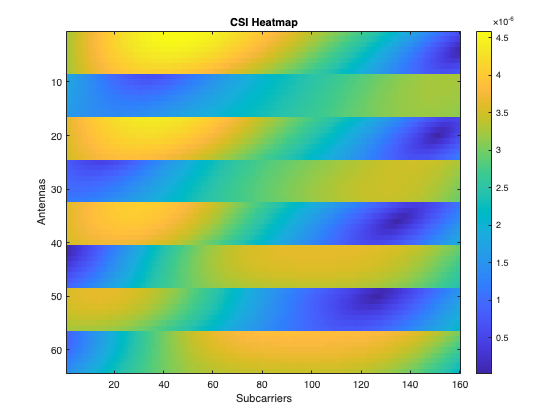

freq_channel = squeeze(freq_channel);
% size(freq_channel);
csi = squeeze(freq_channel(1,:,:));

imagesc(abs(csi)); % Use abs if CSI contains complex numbers
colorbar; % Add color bar for reference
title('CSI Heatmap');
xlabel('Subcarriers');
ylabel('Antennas');

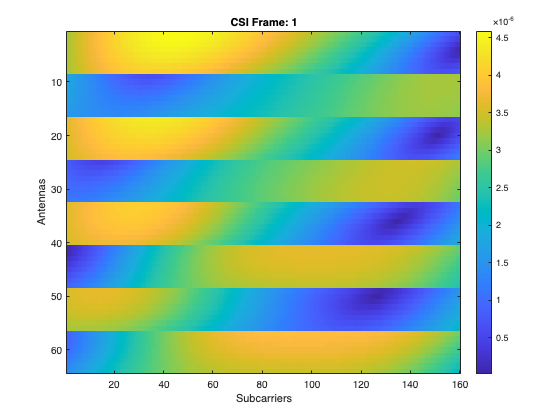

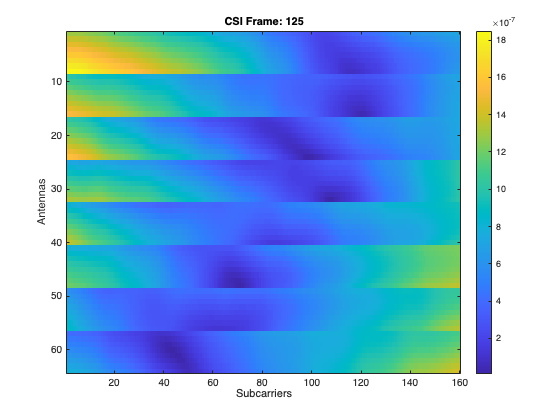

% Create a figure for the animation

figure;
for frame = 1:size(freq_channel, 1) % Loop through all 450 frames
    % Extract the current frame
    csi_frame = squeeze(freq_channel(frame, :, :)); % [64 x 160]
    
    % Visualize the frame as a heatmap
    imagesc(abs(csi_frame)); % Use abs if data is complex
    colorbar; % Add color bar
    title(['CSI Frame: ', num2str(frame)]);
    xlabel('Subcarriers');
    ylabel('Antennas');
    
    % Pause to create animation effect
    pause(0.1); % Adjust pause duration to control animation speed
end

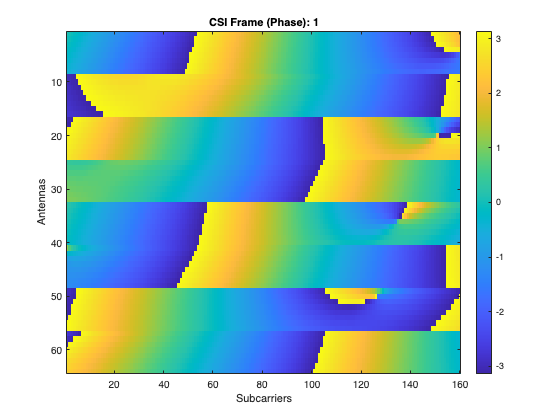

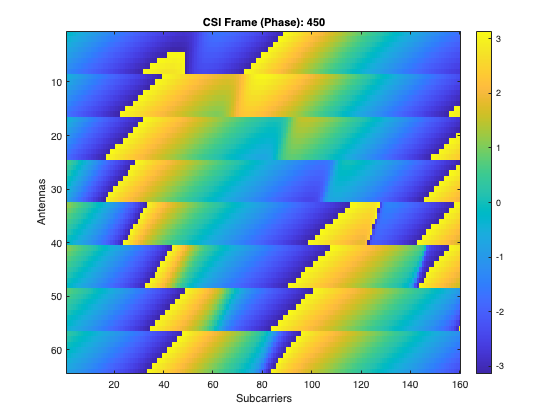


figure;
for frame = 1:size(freq_channel, 1) % Loop through all 450 frames
    % Extract the current frame
    csi_frame = squeeze(freq_channel(frame, :, :)); % [64 x 160]
    
    % Visualize the frame as a heatmap
    imagesc(angle(csi_frame)); % Use abs if data is complex
    colorbar; % Add color bar
    title(['CSI Frame (Phase): ', num2str(frame)]);
    xlabel('Subcarriers');
    ylabel('Antennas');
    
    % Pause to create animation effect
    pause(0.1); % Adjust pause duration to control animation speed
end